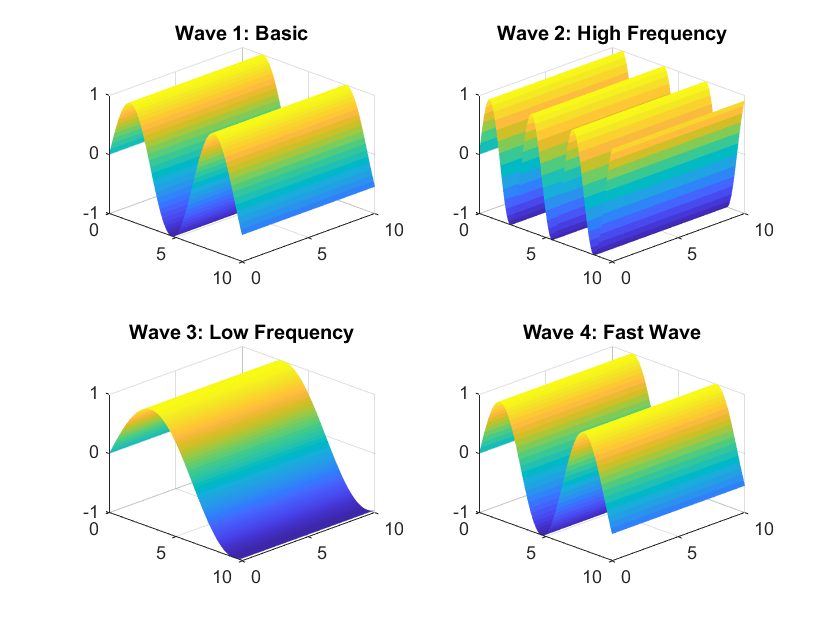

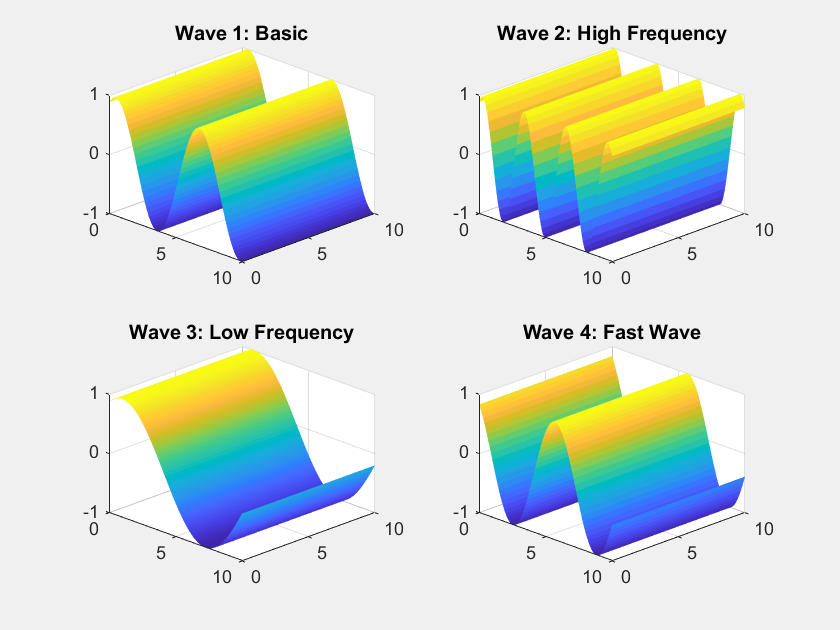

clc;
clear;
close all;

%% =========================
% SPACE SETUP
%% =========================
x = 0:0.1:10;

c = 1; % wave speed

figure;

%% =========================
% ANIMATION LOOP
%% =========================
for t = 0:0.2:10

    % Create 2D grid (space only)
    [X, Y] = meshgrid(x, x); % square surface for 3D look

    % 4 different wave surfaces
    Z1 = sin(X - c*t);
    Z2 = sin(2*X - c*t);
    Z3 = sin(0.5*X - c*t);
    Z4 = sin(X - 2*c*t);

    clf;

    %% =========================
    % WAVE 1
    %% =========================
    subplot(2,2,1);
    surf(X, Y, Z1, 'EdgeColor', 'none');
    title('Wave 1: Basic');
    zlim([-1 1]);
    view(45,30);
    grid on;

    %% =========================
    % WAVE 2
    %% =========================
    subplot(2,2,2);
    surf(X, Y, Z2, 'EdgeColor', 'none');
    title('Wave 2: High Frequency');
    zlim([-1 1]);
    view(45,30);
    grid on;

    %% =========================
    % WAVE 3
    %% =========================
    subplot(2,2,3);
    surf(X, Y, Z3, 'EdgeColor', 'none');
    title('Wave 3: Low Frequency');
    zlim([-1 1]);
    view(45,30);
    grid on;

    %% =========================
    % WAVE 4
    %% =========================
    subplot(2,2,4);
    surf(X, Y, Z4, 'EdgeColor', 'none');
    title('Wave 4: Fast Wave');
    zlim([-1 1]);
    view(45,30);
    grid on;

    pause(0.1);

end